# Exercise 2.4 - Rectangular periodic pulse

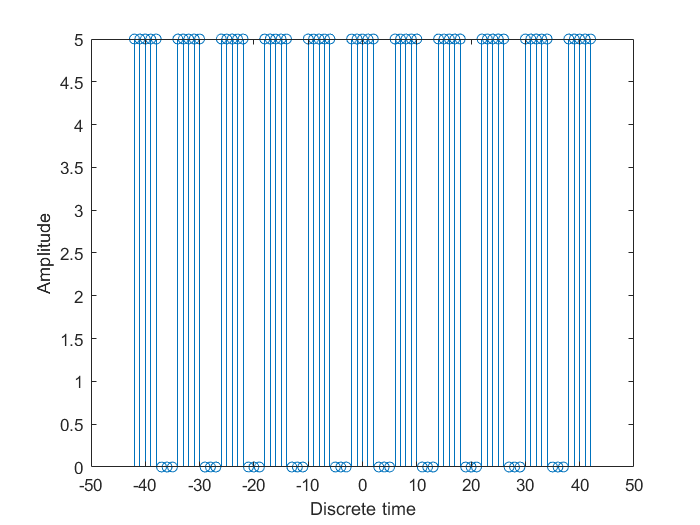

% Let's plot a periodic rectangular signal.
% First, we generate a stream of deltas of period N = 8 made of 81 samples (-40 ≤ n ≤ 40).
deltas = zeros(1, 81);
deltas(1 : 8 : 81) = 1;

% Next, let's generate a rectangular pulse of amplitude 5 and a duration of 5 samples, centered
% around the origin.
nrect = -2 : 2;
rect = zeros(1, 5);
rect(find(nrect == -2) : find(nrect == 2)) = 5;

% Finally, we can compute the convolution between the stream of deltas and the pulse to create signal periodic.
y = conv(deltas, rect);
ny = -42 : 42;
stem(ny, y);
xlabel('Discrete time'), ylabel('Amplitude')